 % ********** Setup the directory for your computer **********
clear
restoredefaultpath
filePath = matlab.desktop.editor.getActiveFilename;
root0 = fileparts(filePath);
addpath(genpath(fullfile(root0,'lib')));
root = fullfile(root0,'data');
root_code = fullfile(root0,'lib','packing');
root_helper = fullfile(root0,'CellSize','helper_functions');
addpath '/Users/hp024/Documents/maelyne/MRI/Diffusion/monte-carlo-simulation-sphere-PGSE-main'
addpath '/Users/hp024/Documents/maelyne/MRI/Diffusion/monte-carlo-simulation-sphere-PGSE-main/data/AMBER_maelyne/lognorm_population_RealisticTests2_V3/sphere_0001'

addpath '/Users/hp024/Documents/maelyne/MRI/Diffusion/monte-carlo-simulation-sphere-PGSE-main/data/AMBER_maelyne/lognorm_population_RealisticTests2_V3'
addpath '/Users/hp024/Documents/maelyne/MRI/Diffusion/monte-carlo-simulation-sphere-PGSE-main/helper_functions'
projname = 'AMBER_maelyne';

## Building the correct path

split = 1; % define which chunk of the sampled parameters to use
tot_split=1; % number of total data splits 

population_type = 'lognorm'; %'uniform' 'lognorm'
population_label = [population_type,'_population_RealisticTests2_V3'];
projectpath = fullfile(root,projname,population_label);
if ~exist(projectpath,'dir')
    mkdir(projectpath)
end
sobol_path = fullfile(projectpath,'sobol_params.txt');

## Define parameters or generate Sobol sampled parameter combinations

% Generate or load parameters
 Dex_sample.lb = 1;
 Dex_sample.ub = 3.5;
 rmean_sample.lb = 5;  % radius mean
 rmean_sample.ub = 40;
 rsd_sample.lb = 0;  % radius std
 rsd_sample.ub = 10;
 f_sample.lb = 0; 
 f_sample.ub = 0.8;
 kappa_dead_sample.lb = 0.04;   % permeability of dead cells (higher than alive cells)
 kappa_dead_sample.ub = 0.3;
 f_alive_sample.lb = 0.0;      % fraction of alive cells among the cells 
 f_alive_sample.ub = 1.0;

 projectpath

projectpath = '/Users/hp024/Documents/maelyne/MRI/Diffusion/monte-carlo-simulation-sphere-PGSE-main/data/AMBER_maelyne/lognorm_population_RealisticTests2_V3'

 tic
 Ncombos = 2^10;
 params = get_sobol_samples_V3(projectpath, root_helper, Dex_sample, rmean_sample, rsd_sample, f_sample, kappa_dead_sample, f_alive_sample, Ncombos);

Sobol file found. Loading in array...


ans = '/Users/hp024/Documents/maelyne/MRI/Diffusion/monte-carlo-simulation-sphere-PGSE-main/data/AMBER_maelyne/lognorm_population_RealisticTests2_V3'

 elapsed_time = toc;
 disp(['Sobol distribution generated in ', num2str(elapsed_time, '%.2f'), ' secondes for ', num2str(Ncombos), ' combos.'])

Sobol distribution generated in 1.72 secondes for 1024 combos.


 % [Dex, rmean, rsd, f, kappa_dead, f_alive]
 extra_points = [
    1.0,    5,  0,   0.6,   0.04,   0;   % extreme low
    3.5,   40, 10,   0.8,    0.3,   1;   % extreme high
    2.0,   30,  0,   0.7,   0.08, 0.6;   % low rsd
    1.0,   40, 10,   0.8,   0.04, 0.1;   % low Dex
    2.5,   30,  8,   0.2,   0.04,   0;   % edge values
    3.5,   40,  0,   0.8,    0.3,   1;   % 2nd attempt convex hull
    3.5,   40,  0,   0.001, 0.04,   0; % 3rd attempt convex hull
    3.5,   40, 10,   0.001,  0.3,   1; % 3rd attempt convex hull
    1.0,    5,  0,   0.001, 0.04,   0; % everything low
    1.0,   40, 10,   0.001, 0.04,   0
    ];
 params = [params; extra_points];

Ncombos = size(params,1);

% Split params for batched processing
% splitindx = Ncombos/tot_split;

% if mod(Ncombos,tot_split)>1
%     splitindx = floor(Ncombos/tot_split);
%     diff = Ncombos- splitindx*tot_split;
%     disp(['Warning: Leaving out final ' num2str(diff) ' param sets to accommodate splitting.'])
% end

% params_in = params((split-1)*splitindx+1:split*splitindx,:);
% disp(['Params_in size: ' num2str(size(params_in,1)) ' samples, ' num2str(size(params_in,2)) ' variables.'])

## Random sphere packing

Sphere 32: 352 alive cells (35.9%), 628 dead cells (64.1%)


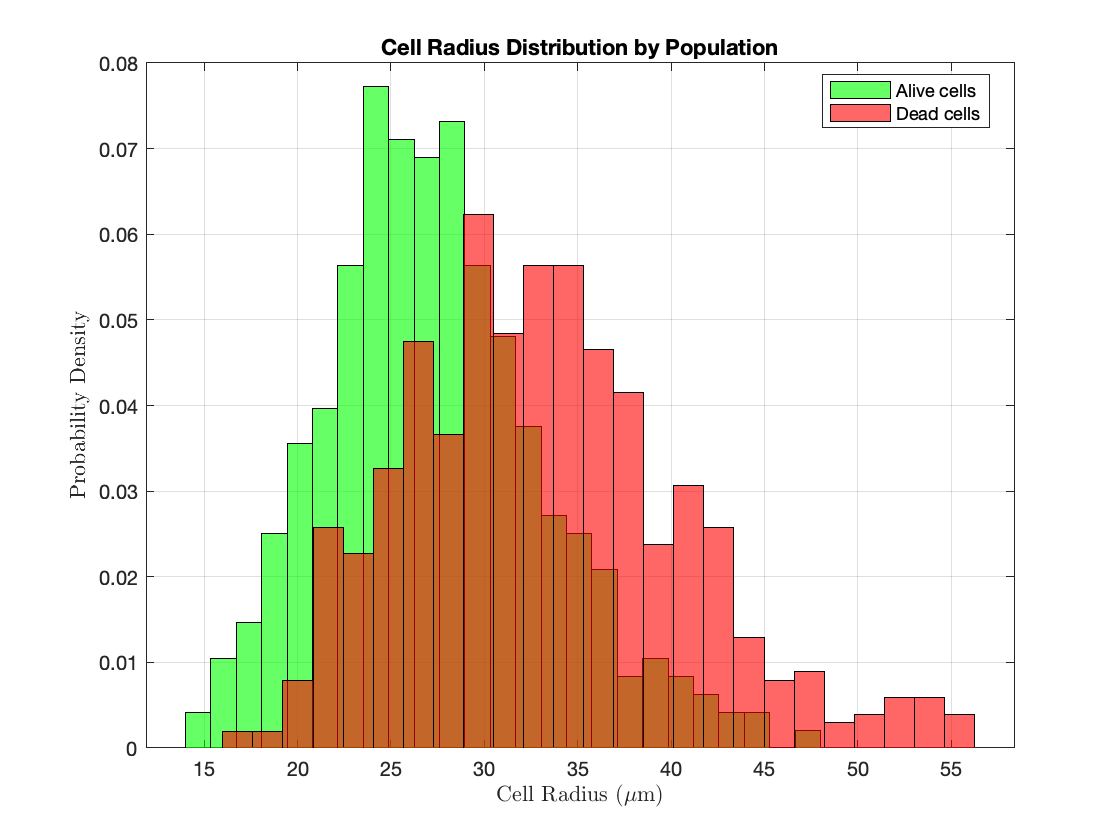

running C ...........
Reading input from file inputN
   eventspercycle : 20
   N : 980
   initialpf : 0.01
   maxpf : 0.22363
   temp : 0.2
   growthrate : 0.001
   maxpressure : 1e+07
   maxcollisionrate : 1e+08
   bidispersityratio : 0.5
   bidispersityfraction : 0.5
   massratio : 1
   hardwallBC : 0
   readfile : read.dat
   writefile : write.dat
   datafile : stats.dat
N = 980
d = 0.0433798
r = 0.0216899
ngrids = 23
DIM = 3
Reading in positions of spheres
need to reduce ngrids to 22
need to reduce ngrids to 21
need to reduce ngrids to 20
need to reduce ngrids to 19
need to reduce ngrids to 18
need to reduce ngrids to 17
need to reduce ngrids to 16
need to reduce ngrids to 15
need to reduce ngrids to 14
need to reduce ngrids to 13
need to reduce ngrids to 12
need to reduce ngrids to 11
need to reduce ngrids to 10
need to reduce ngrids to 9
need to reduce ngrids to 8
need to reduce ngrids to 7
b.pf = 0.269747
b.pressure = 2.33421
b.collisionrate = 25857.4
Elapsed time is 0.299815 se

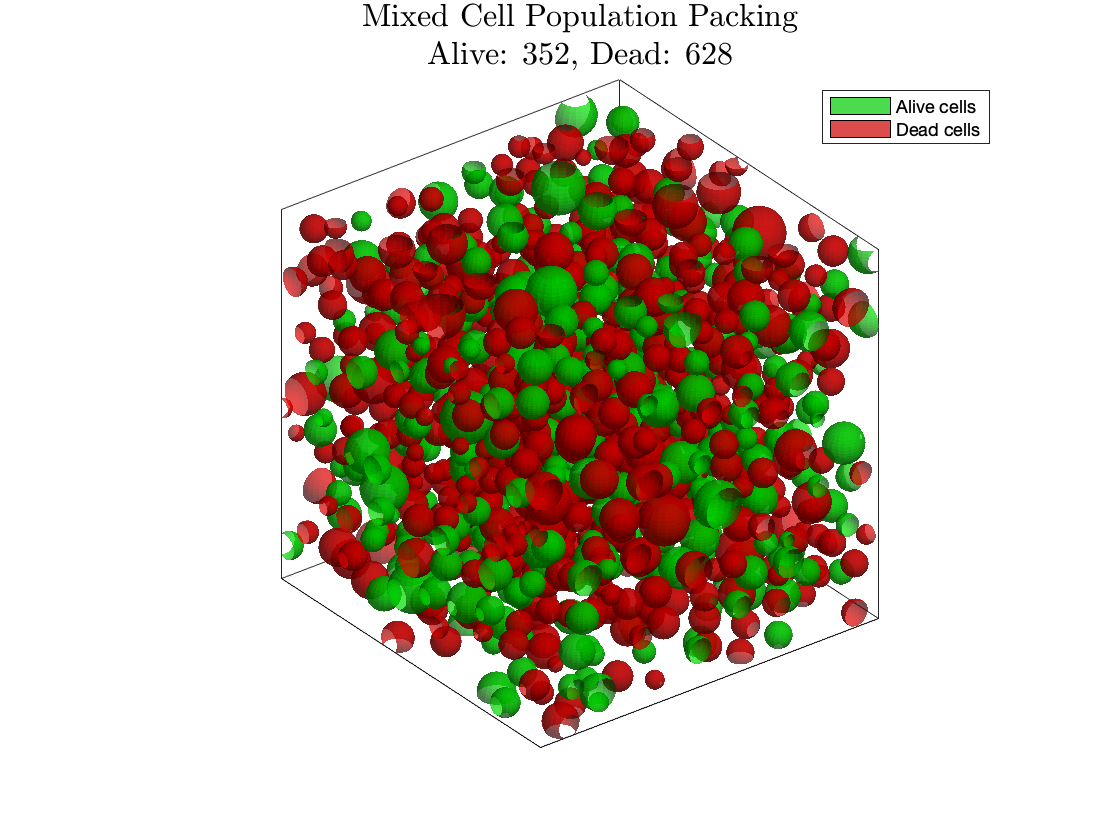

Ncombos = size(params,1);

% Assign variable params:
Dex =   params(1:Ncombos,1);
rmean = params(1:Ncombos,2);
rsd =   params(1:Ncombos,3);
f   =   params(1:Ncombos,4);
kappa_dead = params(1:Ncombos,5);
f_alive = params(1:Ncombos,6);
Delta = ones(Ncombos,1)*[15 45 75];

% Assign fixed params: 

% Sequence params
pulse_width = 4; % pulse width, ms

% b-values
bval = [0, 0.25, 0.5, 0.7, 0.8, 1.0, 1.2, 1.6, 2.0, 3.5];  % ms/um^2
bvec = [1 0 1; -1 0 1; 0 1 1; 0 1 -1; 1 1 0; -1 1 0]./sqrt(2);  % gradient directions in x y and z

kappa_alive = 0.03;     % permeability of alive cells, um/ms

% Simulation parameters
N = 980;                % define number of spheres
dt = 2e-4;              % time of each step, ms
NPar = 1e5;             % # random walkers
Din = 1;                % ICS diffusivity, um^2/ms
pinit = 3;              % initial position, 1=ICS, 2=ECS, 3=ICS+ECS, 4=center
threadpb = 256;         % thread per block for cuda

% Generate randomly packed spheres and save simulation parameters
t1 = tic;
for ii = 32:32

    % Model params
    Dexi = Dex(ii);
    ri = rmean(ii);
    ri_sd = rsd(ii);
    fi = f(ii);
    kappa_deadi = kappa_dead(ii);
    f_alivei = f_alive(ii);
    TD = Delta(ii,:);

    TN = ceil((max(TD)+min(TD))/dt); % # steps

    % Sequence params
    pwi = pulse_width(1);
    Td = pwi*ones(size(TD));         % pulse width, ms

    if ri_sd > ri
        ri_sd = ri;
    end

    target = fullfile(root,projname,population_label,[sprintf('plot_sphere_%04u',ii)]);
    mkdir(target);

    % New: Generate mixed cell population with different properties
    cells.target_rad = ri;
    cells.std_rad = ri_sd;
    cells.population_perc = 1;
    cells.doplot = true;
    
    % Generate radius distribution
    switch population_type
    case 'lognorm'
        [rinit, kappa_init, cellType, outputparams] = create_cell_distribution_V2( ...
    cells, N, f_alivei, kappa_alive, kappa_deadi);
        %rinit
        %kappa_init
        %cellType
        %outputparams
        
    case 'uniform'
        rinit = cells.target_rad*ones(N,1);
    end
    
    % Save permeability
    fileID = fopen(fullfile(target,'phantom_kappa.txt'),'w');
    fprintf(fileID,'%.6f\n', kappa_init);
    fclose(fileID);
    
    % Save types
    fileID = fopen(fullfile(target,'phantom_cellType.txt'),'w');
    fprintf(fileID,'%d\n',cellType);
    fclose(fileID);
    
    % Statistics over populations
    n_alive = sum(cellType == 0);
    n_dead = sum(cellType == 1);
    
    fprintf('Sphere %d: %d alive cells (%.1f%%), %d dead cells (%.1f%%)\n', ...
        ii, n_alive, 100*n_alive/N, n_dead, 100*n_dead/N);
    
    if cells.doplot
        figure;
        hold on;
        histogram(rinit(cellType==0), 25, 'Normalization', 'pdf', ...
            'FaceColor', 'green', 'FaceAlpha', 0.6, 'DisplayName', 'Alive cells');
        histogram(rinit(cellType==1), 25, 'Normalization', 'pdf', ...
            'FaceColor', 'red', 'FaceAlpha', 0.6, 'DisplayName', 'Dead cells');
        title('Cell Radius Distribution by Population');
        xlabel('Cell Radius ($\mu$m)', 'Interpreter', 'latex');
        ylabel('Probability Density', 'Interpreter', 'latex');
        legend('Location', 'best');
        grid on;
        box on;
        hold off;
    end
    
    % Save population parameters (modified format)
    fileID = fopen(fullfile(target,'population_para.txt'),'w');
    fprintf(fileID,sprintf('%g\n%g\n%g\n%g\n%g\n%g\n%g\n', ...
        ri, ri_sd, cells.population_perc, fi, ...
        kappa_alive, kappa_deadi, f_alivei));
    fclose(fileID);

    % Generate packing
    ps = packsph_necrosis();     % class for randomly packed spehres
    maxdensity = fi;    % maximal spherical volume fraction
    hardwallBC = 0;     % boundary condition, 0 for periodic, 1 for hard wall

    if ii==1
        compileFlag = 1;    % compile Donev's C code
    else                
        compileFlag = 0;    
    end
    n = 200;            % matrix size of the lookup table, n x n x n
    gap = 0;            % minimal distance between spheres (µm), default=0
    ps.packing(maxdensity,hardwallBC,rinit,root_code,target,compileFlag,n,gap,cellType,kappa_init)

    % Check packing
    nbin = 10;
    oldFolder = pwd;
    sphere_folder = sprintf('/Users/hp024/Documents/maelyne/MRI/Diffusion/monte-carlo-simulation-sphere-PGSE-main/data/AMBER_maelyne/lognorm_population_RealisticTests2_V3/sphere_%04u', ii);
    cd(sphere_folder);
    %ps.plothist(rinit,nbin)
    
    % Plot packing with color coding by cell type
    xc = load('phantom_xCir.txt');
    yc = load('phantom_yCir.txt');
    zc = load('phantom_zCir.txt');
    rc = load('phantom_rCir.txt');
    
    % Plot for mix population
    ps.plotpack_mixed(xc, yc, zc, rc, cellType);
    
    cd(oldFolder);
    
    % Save simulation parameters (modified format)
    fileID = fopen(fullfile(target,'simParamInput.txt'),'w');
    fprintf(fileID,sprintf('%g\n%u\n%u\n%g\n%g\n%g\n%g\n%g\n%u\n%u\n', ...
        dt, TN, NPar, Din, Dexi, kappa_alive, kappa_deadi, f_alivei, pinit, threadpb));
    fclose(fileID);

    % Create b-table for wide pulse PGSE
    fid = fopen(fullfile(target,'diff_time.txt'),'w');
    fprintf(fid,sprintf('%u\n',TD));
    fclose(fid);

    % Save additional file for diffusion times
    fid = fopen(fullfile(target,'TD_array.txt'),'w');
    fprintf(fid,sprintf('%u\n',TD));
    fclose(fid);

    NDelta = numel(TD);
    DELdel = zeros(NDelta,2);
    for kk = 1:numel(TD)
        DELdel(kk,:) = [TD(kk), Td(kk)];
    end
    DELdel = DELdel.';
    DELdel = DELdel(:);
    fid = fopen(fullfile(target,'gradient_NDelta.txt'),'w');
    fprintf(fid,sprintf('%u\n',NDelta));
    fclose(fid);

    fid = fopen(fullfile(target,'gradient_DELdel.txt'),'w');
    fprintf(fid,sprintf('%.8f\n',DELdel));
    fclose(fid);
    
    ig = 0;
    btab = zeros(numel(bval)*size(bvec,1),4);
    btab_vals = zeros(length(bval).*size(bvec,1),1);
    for jj = 1:numel(bval)
        bvalj = bval(jj);
        for kk = 1:size(bvec,1)
            ig = ig+1;
            bveck = bvec(kk,:);
            btab(ig,:) = [bvalj bveck];
            btab_vals(ig) = bvalj*1000;
        end
    end
    btab = btab.';
    btab = btab(:);
    fid = fopen(fullfile(target,'gradient_Nbtab.txt'),'w');
    fprintf(fid,sprintf('%u\n',numel(bval)*size(bvec,1)));
    fclose(fid);

    fid = fopen(fullfile(target,'gradient_btab.txt'),'w');
    fprintf(fid,sprintf('%.8f\n',btab));
    fclose(fid);

    fid = fopen(fullfile(target,'gradient_bvalstab.txt'),'w');
    fprintf(fid,sprintf('%u\n',btab_vals));
    fclose(fid);
    
    % Save statistics on populations
    fileID = fopen(fullfile(target,'population_stats.txt'),'w');
    fprintf(fileID,'Total cells: %d\n', N);
    fprintf(fileID,'Alive cells: %d (%.1f%%)\n', n_alive, 100*n_alive/N);
    fprintf(fileID,'Dead cells: %d (%.1f%%)\n', n_dead, 100*n_dead/N);
    fprintf(fileID,'Alive permeability: %g um/ms\n', kappa_alive);
    fprintf(fileID,'Dead permeability: %g um/ms\n', kappa_deadi);
    fprintf(fileID,'Mean radius alive: %g um\n', mean(rinit(cellType==0)));
    fprintf(fileID,'Mean radius dead: %g um\n', mean(rinit(cellType==1)));
    fprintf(fileID,'Std radius alive: %g um\n', std(rinit(cellType==0)));
    fprintf(fileID,'Std radius dead: %g um\n', std(rinit(cellType==1)));
    fclose(fileID);
end

      
disp('------------ Finished all sphere packing! --------------')

------------ Finished all sphere packing! --------------


t1_out = toc(t1);
disp(['Elapsed time is ' num2str(t1_out) ' seconds'])

Elapsed time is 12.6735 seconds



% slurm_dir = '/Users/hp024/Documents/maelyne/MRI/Diffusion/monte-carlo-simulation-sphere-PGSE-main/submit_sphere_array.slurm';
% outer_target = fullfile(root,projname,population_label);
% copyfile(slurm_dir,outer_target);

% NOTE: if you want to change the param file after without repeating sphere
% packing, you can, for example, run something like...
% find . -type f -name "sim_para.txt" -exec -i sed 's/1e5/1e6/g' {} +

## New Method: Submit complete batch to run in parallel:

% cd(outer_target);
% 
% % --- Configuration ---
% total_experiments = splitindx; % The total number of sphere experiments you want to run
% chunk_size = 60;         % The number of jobs per submission (your cluster's limit)
% slurm_script_name = 'submit_sphere_array.slurm'; % The name of your Slurm template script
% poll_interval_seconds = 30; % Time to wait between checking the queue (in seconds)
% user_name = 'jmarchan'; % Your username for the squeue command
% 
% fprintf('--- Starting Campaign Manager ---\n');
% fprintf('Total Experiments to Submit: %d\n', total_experiments);
% fprintf('Submitting in chunks of: %d\n\n', chunk_size);
% 
% % % Fix this later: must change number of threads in param file...:
% % paramcommand = ['find . -type f -name "sim_para.txt" -exec sed -i ''8c',num2str(threadpb),''' {} +'];
% % [status, cmdout] = system(paramcommand);
% 
% % --- Main Loop to Submit Chunks ---
% for start_index = 1:chunk_size:total_experiments
%     
%     % Calculate the end index for the current chunk
%     end_index = start_index + chunk_size - 1;
%     if end_index > total_experiments
%         end_index = total_experiments;
%     end
% 
%     % Correcting sim_para.txt file if necessary:
%     
%     fprintf('--- Submitting Batch: Experiments %d to %d ---\n', start_index, end_index);
%     
%     % 1. Construct the sbatch command with the correct array range
%     sbatch_command = sprintf('sbatch --array=%d-%d %s', start_index, end_index, slurm_script_name);
%     
%     % 2. Submit the job and capture the output
%     [status, cmdout] = system(sbatch_command);
%     
%     % Check if the submission was successful
%     if status ~= 0
%         fprintf('Error submitting job chunk! Stopping campaign.\n');
%         disp(cmdout);
%         return; % Exit the script if submission fails
%     end
%     
%     % 3. Extract the Job ID from the output string "Submitted batch job 12345"
%     job_id_cell = textscan(cmdout, 'Submitted batch job %d');
%     if isempty(job_id_cell{1})
%         fprintf('Could not parse Job ID from sbatch output. Stopping campaign.\n');
%         disp(cmdout);
%         return;
%     end
%     job_id = job_id_cell{1};
%     job_id_str = num2str(job_id);
%     
%     fprintf('Batch submitted successfully with Job ID: %s\n', job_id_str);
%     
%     % 4. Monitor the queue until this Job ID disappears
%     fprintf('Now monitoring job %s. Will check every %d seconds...\n', job_id_str, poll_interval_seconds);
%     
%     is_job_running = true;
%     while is_job_running
%         % Wait for the specified interval
%         pause(poll_interval_seconds);
%         
%         % Check the queue for your jobs
%         squeue_command = sprintf('squeue -u %s', user_name);
%         [~, queue_output] = system(squeue_command);
%         
%         % Check if the Job ID still exists in the queue output
%         if contains(queue_output, job_id_str)
%             % fprintf('[%s] Batch %s is still running or pending. Waiting...\n', datestr(now), job_id_str);
%             is_job_running = true;
%         else
%             fprintf('[%s] Batch %s has completed!\n\n', datestr(now), job_id_str);
%             is_job_running = false;
%         end
%     end
% end
% 
% fprintf('--- All experiment batches have been submitted and completed. ---\n');
% fprintf('--- Campaign Finished! ---\n');
% 
% 
% return


## Load data for all time points

Ncombos = 1034;
streamline = 1;
population_type = 'lognorm'; %'uniform' 'lognorm'
population_label = [population_type,'_population_RealisticTests2_V3'];
projectpath = fullfile(root,projname,population_label);
bval = [0, 0.25, 0.5, 0.7, 0.8, 1.0, 1.2, 1.6, 2.0, 3.5];
bvec = [1 0 1; -1 0 1; 0 1 1; 0 1 -1; 1 1 0; -1 1 0]./sqrt(2);

% Arrays to stock results for each geometry
Dtot = []; % time-dependent diffusivity for all geometries
Ktot = []; % time-dependent kurtosis for all geometries
dtot = []; % mean diffusivity (um) for all geometries
ftot = []; % intra-spherical volume fraction for all geometries
f_alivetot = []; % alive cell fraction among the cells
k_alivetot = []; % membrane permeability (um/ms) for alive cells
k_deadtot = []; % membrane permeability (um/ms) for dead cells
n_alivetot = []; % number of alive cells for all geometries
n_deadtot = []; % number of dead cells for all geometries
percent_alivetot = []; % percentage of alive cells for all geometries
percent_deadtot = []; % percentage of dead cells for all geometries
NParICS_alive_tot = []; % evolution of alive cells in ICS for all geometries
NParICS_dead_tot = []; % evolution of dead cells in ICS for all geometries

Ditot = []; % intrinsic diffusivity inside spheres (um^2/ms) for all geometries
Detot = []; % intrinsic diffusivity outside spheres (um^2/ms) for all geometries
tptot = []; % time to the kurtosis peak (ms) for all geometries

test_data = projectpath % outer_target; %fullfile(root,projname,[population_type,'_population_CellOnly_V3']) %,['batch_' num2str(split)]);

test_data = '/Users/hp024/Documents/maelyne/MRI/Diffusion/monte-carlo-simulation-sphere-PGSE-main/data/AMBER_maelyne/lognorm_population_RealisticTests2_V3'

disp('Note: please fix and add batch description.');

Note: please fix and add batch description.


if ~exist(test_data,'dir')
    mkdir(test_data);
end
cd(test_data);

sig_diravg_all = []; %zeros(numel(TD),numel(bval)+1);
TDtot = [];
params = zeros(Ncombos, 10); % 10 parameters saved in sim_para.txt 

%figure;
for i = 1:Ncombos
    current_target = fullfile(root,projname,population_label,sprintf('sphere_%04u',i));
    
    % Change simulation parameters
    param_i = load(fullfile(current_target, 'sim_para.txt')); % Load sim parameters
    params(i,:) = param_i(:)'; % Store as row in a matrix
    
    % New function for 2 populations of cells
    rms = simul3Dsphere_cuda_pgse_bvec_necrosis(current_target);
    
    % signal extraction
    sigi = rms.sig;
    bvali = rms.bval;
    
    % Populaion statistics
    stats = rms.getPopulationStats();
    f_alivetot = cat(1, f_alivetot, rms.f_alive);
    k_alivetot = cat(1, k_alivetot, rms.kappa_alive);
    k_deadtot = cat(1, k_deadtot, rms.kappa_dead);
    
    if ~isempty(stats.n_alive)
        n_alivetot = cat(1, n_alivetot, stats.n_alive);
        n_deadtot = cat(1, n_deadtot, stats.n_dead);
        percent_alivetot = cat(1, percent_alivetot, stats.percent_alive);
        percent_deadtot = cat(1, percent_deadtot, stats.percent_dead);
    else
        % If stats are not there
        n_alivetot = cat(1, n_alivetot, NaN);
        n_deadtot = cat(1, n_deadtot, NaN);
        percent_alivetot = cat(1, percent_alivetot, NaN);
        percent_deadtot = cat(1, percent_deadtot, NaN);
    end
    
    % Time evolution of populations
    NParICS_alive_tot = cat(2, NParICS_alive_tot, rms.NParICS_alive);
    NParICS_dead_tot = cat(2, NParICS_dead_tot, rms.NParICS_dead);

    Di = zeros(rms.NDel,1);
    Ki = zeros(rms.NDel,1);
    sig_diravg = zeros(rms.NDel,length(bval));
    
    %figure;
    for k = 1:rms.NDel
        sigj = sigi(:,k);
        [C, IA, IC] = unique(bvali);
        sigk = zeros(numel(C),1);
        for l = 1:numel(C)
            Ik = IC==l;
            sigk(l) = mean(sigj(Ik)); % averages the 3 directions for each b value
        end
        sig_diravg(k,:) = sigk;
        
        % Negative values management
        Ineg = find(sigk<0);
        if ~isempty(Ineg)
            fprintf('Negative signal value found for sphere %u at bvalue %u.\n',i,bval(Ineg)*1000);
            fprintf('Excluding from calculation of Deff. \n');
            C = C(1:Ineg-1);
            sigk = sigk(1:Ineg-1);
            A = [-C, 1/6*C.^2, C.^(3:5)]; % A = [-C, 1/6*C.^2] if less than 6 bvalues
            X = A\log(sigk(:));
            Di(k) = X(1);
            Ki(k) = X(2)/X(1)^2;
        else
            A = [-C, 1/6*C.^2, C.^(3:5)]; % A = [-C, 1/6*C.^2] if less than 6 bvalues
            X = A\log(sigk(:));
            Di(k) = X(1);
            Ki(k) = X(2)/X(1)^2;
        end
    end
    
    clf;
    
    % Save results
    Dtot = cat(2,Dtot,Di);
    Ktot = cat(2,Ktot,Ki);
    TDtot = cat(2,TDtot,rms.Del);
    [~,I] = max(Ki);
    tptot = cat(1, tptot, rms.Del(I));
    
    % Save individual data
    nm = fullfile(current_target,"sig_diravg.txt");
    writematrix(sig_diravg,nm);
    sig_diravg_all = cat(3,sig_diravg_all,sig_diravg);
    nm = fullfile(current_target,"Dcoeff_list.txt");
    writematrix(Di,nm);
    
    % Save population data
    nm = fullfile(current_target,"NParICS_alive_evolution.txt");
    writematrix(rms.NParICS_alive,nm);
    nm = fullfile(current_target,"NParICS_dead_evolution.txt");
    writematrix(rms.NParICS_dead,nm);
    
    % Geometry
    ri = load(fullfile(current_target,'phantom_rCir.txt'));
    vi = load(fullfile(current_target,'phantom_res.txt'));
    dtot = cat(1, dtot, mean(ri)*vi*2);
    ftot = cat(1, ftot, sum(4/3*pi*ri.^3));
    
    % Diffusion parameters
    Ditot = cat(1, Ditot, rms.Din);
    Detot = cat(1, Detot, rms.Dex);
end

Negative signal value found for sphere 5 at bvalue 3500.


Excluding from calculation of Deff. 


Negative signal value found for sphere 206 at bvalue 3500.


Excluding from calculation of Deff. 


Negative signal value found for sphere 207 at bvalue 3500.


Excluding from calculation of Deff. 


Negative signal value found for sphere 454 at bvalue 3500.


Excluding from calculation of Deff. 


Negative signal value found for sphere 760 at bvalue 3500.


Excluding from calculation of Deff. 


Negative signal value found for sphere 760 at bvalue 3500.


Excluding from calculation of Deff. 


Negative signal value found for sphere 769 at bvalue 3500.


Excluding from calculation of Deff. 


Negative signal value found for sphere 772 at bvalue 3500.


Excluding from calculation of Deff. 


Negative signal value found for sphere 772 at bvalue 3500.


Excluding from calculation of Deff. 


Negative signal value found for sphere 772 at bvalue 3500.


Excluding from calculation of Deff. 


Negative signal value found for sphere 774 at bvalue 3500.


Excluding from calculation of Deff. 


Negative signal value found for sphere 775 at bvalue 3500.


Excluding from calculation of Deff. 


Negative signal value found for sphere 775 at bvalue 3500.


Excluding from calculation of Deff. 


Negative signal value found for sphere 1031 at bvalue 2000.


Excluding from calculation of Deff. 


Negative signal value found for sphere 1031 at bvalue 2000.
Negative signal value found for sphere 3500 at bvalue 

Excluding from calculation of Deff. 




% Save D vals
nm = fullfile(test_data,'Dcoeff_list_all.txt');
writematrix(Dtot,nm);

% Save input params (maintenant avec 10 paramètres au lieu de 9)
nm = fullfile(test_data,'params_in.txt');
writematrix(params(1:size(Dtot,2),:),nm);

% Save TD arrays
nm = fullfile(test_data,'TD_all.txt');
writematrix(TDtot,nm);

% Save population parameters
nm = fullfile(test_data,'f_alive_all.txt');
writematrix(f_alivetot,nm);
nm = fullfile(test_data,'kappa_alive_all.txt');
writematrix(k_alivetot,nm);
nm = fullfile(test_data,'kappa_dead_all.txt');
writematrix(k_deadtot,nm);

% Save population statistics
nm = fullfile(test_data,'n_alive_all.txt');
writematrix(n_alivetot,nm);
nm = fullfile(test_data,'n_dead_all.txt');
writematrix(n_deadtot,nm);
nm = fullfile(test_data,'percent_alive_all.txt');
writematrix(percent_alivetot,nm);
nm = fullfile(test_data,'percent_dead_all.txt');
writematrix(percent_deadtot,nm);

% Save temporal evolution of populations
nm = fullfile(test_data,'NParICS_alive_all.txt');
writematrix(NParICS_alive_tot,nm);
nm = fullfile(test_data,'NParICS_dead_all.txt');
writematrix(NParICS_dead_tot,nm);

% Save summary on population
population_summary = table(f_alivetot, k_alivetot, k_deadtot, n_alivetot, n_deadtot, ...
                          percent_alivetot, percent_deadtot, ...
                          'VariableNames', {'f_alive', 'kappa_alive', 'kappa_dead', ...
                          'n_alive', 'n_dead', 'percent_alive', 'percent_dead'});
nm = fullfile(test_data,'population_summary.csv');
writetable(population_summary, nm);

% Summary plot
if ~streamline
    figure('Name', 'Population Statistics');
    subplot(2,2,1);
    histogram(f_alivetot, 'Normalization', 'probability');
    xlabel('Fraction of Alive Cells');
    ylabel('Probability');
    title('Distribution of Alive Cell Fractions');
    
    subplot(2,2,2);
    histogram(percent_alivetot, 'Normalization', 'probability');
    xlabel('Percentage of Alive Cells (%)');
    ylabel('Probability');
    title('Distribution of Alive Cell Percentages');
    
    subplot(2,2,3);
    scatter(k_alivetot, k_deadtot);
    xlabel('Kappa Alive (μm/ms)');
    ylabel('Kappa Dead (μm/ms)');
    title('Permeability Correlation');
    grid on;
    
    subplot(2,2,4);
    boxplot([k_alivetot, k_deadtot], 'Labels', {'Alive', 'Dead'});
    ylabel('Permeability (μm/ms)');
    title('Permeability Comparison');
    
    % Save plots
    saveas(gcf, fullfile(test_data, 'population_analysis.png'));
    
    % Mean evolution of population
    if size(NParICS_alive_tot, 1) > 1 && size(NParICS_dead_tot, 1) > 1
        figure('Name', 'Average Population Evolution');
        TD_mean = mean(TDtot, 2);
        alive_mean = mean(NParICS_alive_tot, 2);
        dead_mean = mean(NParICS_dead_tot, 2);
        alive_std = std(NParICS_alive_tot, 0, 2);
        dead_std = std(NParICS_dead_tot, 0, 2);
        
        errorbar(TD_mean, alive_mean, alive_std, 'g-', 'LineWidth', 2, 'DisplayName', 'Alive Cells');
        hold on;
        errorbar(TD_mean, dead_mean, dead_std, 'r-', 'LineWidth', 2, 'DisplayName', 'Dead Cells');
        xlabel('Diffusion Time (ms)');
        ylabel('Fraction in ICS');
        title('Average Population Evolution in ICS');
        legend('show');
        grid on;
        
        saveas(gcf, fullfile(test_data, 'average_population_evolution.png'));
    end
end

% Save signals (commenté dans l'original)
%nm = fullfile(training_data,'sig_diravg_all.txt');
%writematrix(sig_diravg_all,nm)

if streamline
    disp('Simulations finished and files successfully saved!');
    fprintf('Population data saved for %d geometries\n', length(f_alivetot));
    fprintf('Average alive cell fraction: %.2f ± %.2f\n', mean(f_alivetot), std(f_alivetot));
    fprintf('Average alive cell percentage: %.1f%% ± %.1f%%\n', mean(percent_alivetot, 'omitnan'), std(percent_alivetot, 'omitnan'));
    return;
end

Simulations finished and files successfully saved!


Population data saved for 1034 geometries


Average alive cell fraction: 0.50 ± 0.29


Average alive cell percentage: 49.9% ± 29.1%


## Checking the influence of pulse width

figure; clf; hold on; 
% pw = 4
pwind = 1; color_in = 'r';
s_in = sig_diravg_all{pwind};
plot(bval,s_in(1,:),[color_in,'-']); % TD = 30 
hold on;
plot(s_in(2,:),[color_in,'--']); % TD = 45
plot(s_in(3,:),[color_in,'.-']); % TD = 70;

% pw = 6
pwind = 2; color_in = 'b';
s_in = sig_diravg_all{pwind};
plot(bval,s_in(1,:),[color_in,'-']); % TD = 30
plot(s_in(2,:),[color_in,'--']); % TD = 45
plot(s_in(3,:),[color_in,'.-']); % TD = 70;

% pw = 8
pwind = 3; color_in = 'k';
s_in = sig_diravg_all{pwind};
plot(bval,s_in(1,:),[color_in,'-']); % TD = 30
plot(s_in(2,:),[color_in,'--']); % TD = 45
plot(s_in(3,:),[color_in,'.-']); % TD = 70;

% pw = 10
pwind = 4; color_in = 'm';
s_in = sig_diravg_all{pwind};
plot(bval,s_in(1,:),[color_in,'-']); % TD = 30
plot(s_in(2,:),[color_in,'--']); % TD = 45
plot(s_in(3,:),[color_in,'.-']); % TD = 70;

## Kurtosis measures....

% Theoretical prediction of time to the kurtosis peak for narrow pulse PG
katot
Detot
tpeak_np = sqrt(2/5*(dtot/2).^3./katot./Detot) + rms.del(1)/3

% Theoretical prediction of time to the kurtosis peak for wide pulse PG
tpeak_wp = sqrt(2/5*(dtot/2).^3./katot./Detot) .* sqrt(16/35*(dtot/2).^2./Ditot/rms.del(1)) + rms.del(1)/3

% Diffusion time (ms)
Del = rms.Del

% intra-spherical residence time (ms)
tr = 1./(katot*3./(dtot/2))

% intra-spherical correlation time (ms)
tD = (dtot/2).^2./Ditot

## EC Diffusion Measures

figure; plot(TD,Dtot);
figure; semilogx(TD,Dtot);
hold on; semilogx(TD,0.58+max(Dtot).*((TD.^-1)./max((TD.^-1)))); legend('Dmeas','t^{-1}','location','best');
xlabel('Diffusion Time (ms)'); ylabel('D_{eff}');
title('Reaching the tortuosity limit with long TD....')

% We expect t^-1 for narrow PGSE...



% We know that Dex is the actual diffusivity. 
% so lets take th elongest TD and find D_eff

% If we consider a diffusion time of TD(2) --> short!
D_limit = squeeze(Dtot(115,:));
tau = sqrt(Dex./D_limit); % Calculate tortuosityy = 

% Vol fraction
figure; plot(f,tau,'*-'); % plot vol fraction vs tortuosity
hold on;
xlabel('Intracellular Volume Fraction');
ylabel('Calculated \tau');

% Porosity
porosity = 1-f;
figure; plot(flip(porosity),flip(tau),'*-'); % plot vol fraction vs tortuosity
hold on;
xlabel('Porosity');
ylabel('Calculated \tau');

% Fit against vol fraction

perc_thresh_ind = 11;
f_in = f(1:perc_thresh_ind)';
tau_in = tau(1:perc_thresh_ind)';
%perc_thresh = 0.65; %f(perc_thresh_ind);
fit_model = fittype(@(A,mu,perc_thresh,x) A*(perc_thresh - x).^(-mu) );
startpts = [0.2 0.8 0.64];
fit_opts = fitoptions(fit_model);
fit_opts.StartPoint = startpts;
fit_opts.Lower = [0 0 0.601];
fit_opts.Upper = [2 3 0.7];
[fit_result,gof] = fit(f_in,tau_in,fit_model,fit_opts);
figure;
plot(fit_result,f_in,tau_in);

phi = 1-f_in;
% Assumes 'phi' is your porosity data (1 - f_ic)
% Assumes 'tau' is your tortuosity data

% 1. DEFINE THE BRUGGEMAN/ARCHIE'S LAW MODEL
% Model is tau = A * phi^(-m)
fit_model_bruggeman = fittype( @(A, m, x) A * x.^(-m) );

% 2. SET STARTING POINTS AND BOUNDS
% [A, m]
startpts = [1.0, 0.75];      % A good physical starting point
lower_bounds = [0.8, 0.1];   % Constrain the search
upper_bounds = [1.2, 2.0];   % Constrain the search

fit_opts = fitoptions(fit_model_bruggeman);
fit_opts.StartPoint = startpts;
fit_opts.Lower = lower_bounds;
fit_opts.Upper = upper_bounds;

% 3. RUN THE FIT
[fit_bruggeman, gof_bruggeman] = fit(phi, tau_in, fit_model_bruggeman, fit_opts);

% 4. DISPLAY AND PLOT
disp(fit_bruggeman);
figure;
plot(fit_bruggeman, phi, tau);
xlabel('Porosity (\phi)');
ylabel('Tortuosity (\tau)');
legend('Data', 'Bruggeman/Archie Fit');

## Compare with tumorSANDI prediction

%f = @() f_in*

## Plot figure: time-dependent kurtosis

close all
d_mean = [5 10 15];               % mean diameter (um)
f      = [0.2 0.4 0.6];           % intra-spherical volume fraction
kappa =  [0.01 0.03 0.05];        % membrane permeability (um/ms)

nrow = 3;
ncol = 3;
figure('unit','inch','position',[0 0 19.37/2 8.98]);
cmap = colormap('lines');
ii = 0;
for i = 1:numel(d_mean)
    for k = 1:numel(f)
        clear h lgtxt
        for l = 1:numel(kappa)
            ii = ii+1;
            Ki = Ktot(:,ii);
            [~,I] = min(abs(tptot(ii)-Del));

            subplot(nrow,ncol,(i-1)*numel(f)+k)
            hold on;
            h(l) = plot(Del, Ki, '-', 'color', cmap(l,:), 'linewidth', 1);
            plot(Del(I), Ki(I), 'v', 'color', cmap(l,:), 'markersize', 8, 'linewidth', 1);
            lgtxt{l} = sprintf('$\\kappa=%.2f$', kappa(l));
        end
        title(sprintf('($d, f$) = (%u $\\mu$m, %.1f)', d_mean(i), f(k)), 'interpreter','latex','fontsize',14)
        if i==1 && k==1
            hl = legend(h, lgtxt, 'interpreter', 'latex', 'box', 'off', 'location', 'northeast', 'fontsize', 14);
            hl.Position = hl.Position + [0.015 0.01 0 0];
            hl.ItemTokenSize = [18 18];
        end

        xticks(0:20:120)

        xlim([0 120]);
        if k==1
            ylim([0 1]);
        elseif k==2
            ylim([0 2]);
        elseif k==3
            ylim([0 4]);
        end
        box on;
        grid on;
        if i==3
            xlabel('$\Delta$, ms', 'interpreter','latex','fontsize',14)
        end
        if k==1
            ylabel('$K(\Delta)$', 'interpreter','latex','fontsize',14)
        end
    end
end

## Plot figure: time to the kurtosis peak

nrow = 1;
ncol = 3;
figure('unit','inch','position',[0 0 19.37/4*3 8.98/2]);
cmap = colormap('lines');
ii = 0;
mk = {'o','d','s'};
for i = 1:numel(d_mean)
    for k = 1:numel(f)
        clear h lgtxt
        for l = 1:numel(kappa)
            ii = ii+1;
            subplot(nrow,ncol,k)
            hold on;
            if tr(ii) < tD(ii)
                h(l) = plot(tptot(ii), tpeak_np(ii), '-', 'color', cmap(i,:),...
                'marker', mk{l}, 'markersize', 8, 'linewidth', 1, 'MarkerFaceColor', 0.85*[1 1 1]);
            else
                h(l) = plot(tptot(ii), tpeak_np(ii), '-', 'color', cmap(i,:),...
                    'marker', mk{l}, 'markersize', 8, 'linewidth', 1);
            end
        end
        title(sprintf('$f$ = %.1f', f(k)), 'interpreter','latex','fontsize',16)
        xlim([0 100]);
        ylim([0 100]);
        box on;
        grid on;
        xlabel('$\Delta_{\rm peak}$, ms', 'interpreter','latex','fontsize',16)
        ylabel('$t_{\rm peak}+\frac{1}{3}\delta$, ms', 'interpreter','latex','fontsize',16)
        hr = refline(1,0); set(hr, 'color','k')
        pbaspect([1 1 1])
        xticks(0:20:100);
        yticks(0:20:100);
    end
end

clear h lgtxt
ii = 0;
for i = 1:numel(kappa)
    ii = ii+1;
    h(ii) = plot(-1, -1, 'k.', 'marker', mk{i}, 'markersize', 8, 'linewidth', 1);
    lgtxt{ii} = sprintf('$\\kappa$ = %.2f $\\mu$m/ms', kappa(i));
end

for i = 1:numel(d_mean)
    ii = ii+1;
    h(ii) = plot(-1, -1, 'k-', 'color', cmap(i,:), 'linewidth', 1);
    lgtxt{ii} = sprintf('$d$ = %u $\\mu$m', d_mean(i));
end

ii = ii+1;
h(ii) = fill([-1 0 0 -1],[1 1 2e2 2e2],0.85*[1 1 1],'edgecolor',0.5*[1 1 1]);
lgtxt{ii} = '$\,\, t_r<t_D$';

hl = legend(h, lgtxt, 'box', 'off', 'location', 'northwest', 'fontsize', 12, 'interpreter', 'latex');
hl.Position = hl.Position + [-0.015 0.015 0 0];
hl.ItemTokenSize = [18 18];